# Examples for using the `derivative` function.

Copyright © 2021 Tamas Kis

## Example #1 - Differentiation over an interval.

*Consider the data set *$\mathbf{y}$ vs. $\mathbf{x}$:


$$\mathbf{x}=\left\lbrack \begin{array}{cccccc}
0\ldotp 12 & 0\ldotp 9 & 2\ldotp 1 & 2\ldotp 95 & 4\ldotp 03 & 4\ldotp 99
\end{array}\right\rbrack$$



$$\mathbf{y}=\left\lbrack \begin{array}{cccccc}
0 & 1\ldotp 2 & 8\ldotp 3 & 26\ldotp 1 & 65\ldotp 04 & 124\ldotp 43
\end{array}\right\rbrack$$


*Estimate and plot the derivative of the underlying function *$y=f\left(x\right)$.

First, input the data into MATLAB.

x = [0.12,0.9,2.1,2.95,4.03,4.99];
f = [0,1.2,8.3,26.1,65.04,124.43];

Differentiating,

df = derivative(x,f);

Plotting the derivative $\textrm{dy}/\textrm{dx}$ of the underlying function $y=f\left(x\right)$ over the interval specified by $\mathbf{x}$,

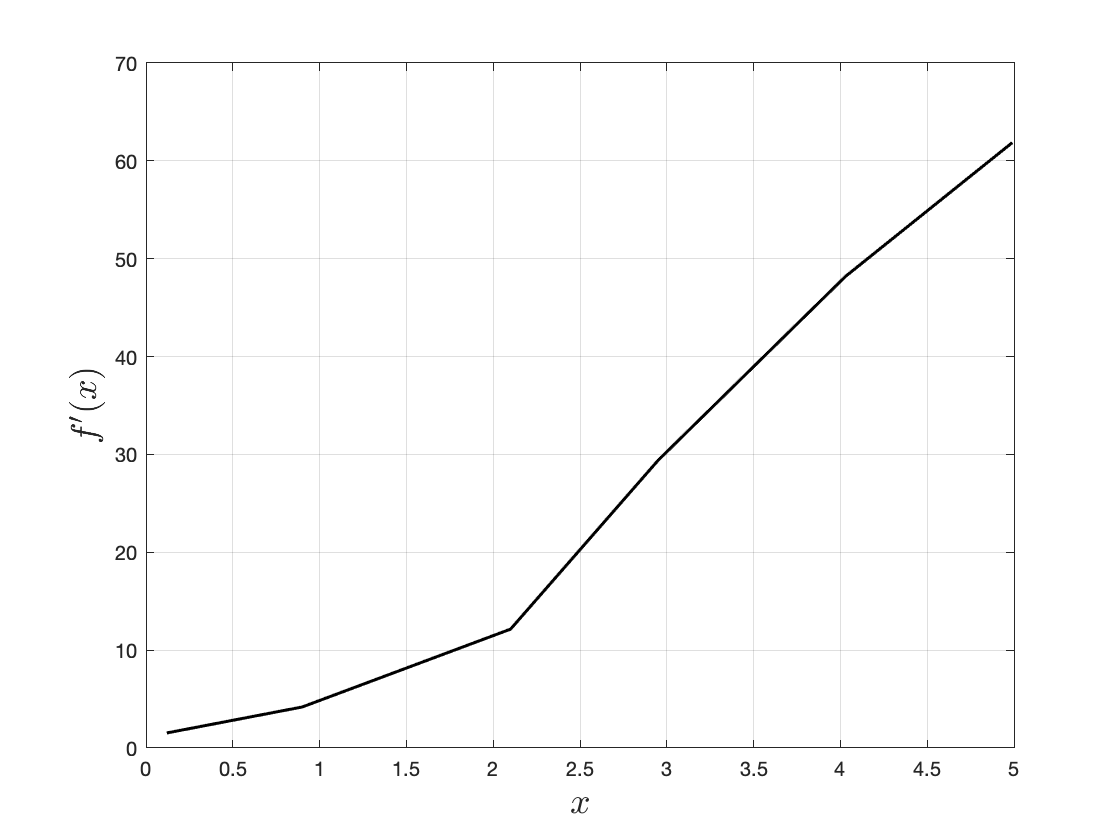

figure;
plot(x,df,'k','linewidth',1.5);
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel("$f'(x)$",'interpreter','latex','fontsize',18);

## Example #2 - Differentiation at a single point.

*Consider the same data set as in Example #1. Estimate the derivative of the underlying function *$y=f\left(x\right)$ at the point $x^* =2\ldotp 5$.

To find $\textrm{dy}/\textrm{dx}$ at $x^* =2\ldotp 5$, we just need to supply an additional input to `derivative`.

df = derivative(x,f,2.5)

df = 20.2652

## Example #3 - Differentiation at multiple points.

*Consider the same data set as in Example #1. Estimate the derivative of the underlying function *$y=f\left(x\right)$ at the points ${\mathbf{x}}^* =\left\lbrack \begin{array}{ccc}
1\ldotp 5 & 2\ldotp 5 & 3\ldotp 5
\end{array}\right\rbrack$.

First, define ${\mathbf{x}}^*$ in MATLAB.

x_star = [1.5,2.5,3.5];

Performing the differentiation,

df = derivative(x,f,x_star)

df =     8.1691   20.2652   38.9741


## Example #4 - Differentiation outside of the data domain.

*Consider the same data set as in Example #1. Estimate the derivative of the underlying function *$y=f\left(x\right)$ at the points $x^* =6$.

We can use the `derivative` function in the same exact way as for Example #2; it will automatically handle differentiation outside of the data set via linear extrapolation.

df = derivative(x,f,6)

df = 76.2398

## Example #5 - Differentiation of a Known Function

*Estimate and plot the derivative of *$f\left(x\right)=x^3$ over the interval $\left\lbrack -3,10\right\rbrack$.

The `derivative` function can only differentiate data. Therefore, we need to create a data set that stores evaluations of $f\left(x\right)$ at many points in the specified interval. To be as accurate as possible, we need a large number of points, so we use a small grid spacing of $\Delta x=0\ldotp 01$.

x = -3:0.01:10;
f = x.^3;

Differentiating,

df = derivative(x,f);

Plotting the derivative of $f\left(x\right)$ over the specified interval,

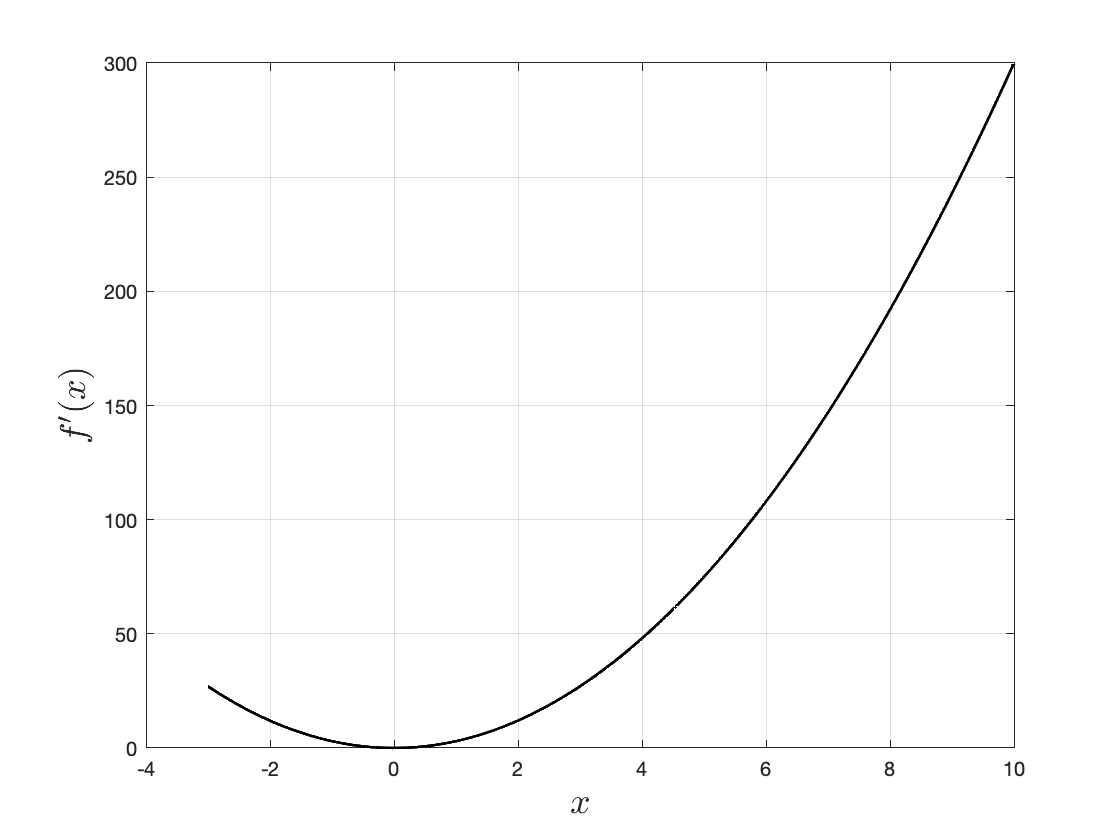

figure;
plot(x,df,'k','linewidth',1.5);
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel("$f'(x)$",'interpreter','latex','fontsize',18);

**Note: **In this case, since the underlying function $f\left(x\right)$ is known, the function `derivest` ([https://www.mathworks.com/matlabcentral/fileexchange/13490-adaptive-robust-numerical-differentiation](https://www.mathworks.com/matlabcentral/fileexchange/13490-adaptive-robust-numerical-differentiation)) will produce more accurate results.